# FIELD CALIBRATION

Script for field calibration using a sample of NaC60. There are two different methods, which lead to similar results (around 1e-4 agreement between the results): 1. Using the function pepperFieldOffset written by Jannik 2. Obtaining the g-value from esfit and from there calculating the field offset

clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\ESP300 Field calibration SK';
% Import
dataRes = importdata([Opt.LFolder, '\', 'RSSMB100A_20200504_cw_052_05mA_harm_1_0.txt']);
dataNonRes = importdata([Opt.LFolder, '\', 'RSSMB100A_20200504_cw_052_05mA_harm_1_1.txt']);

Baseline correction

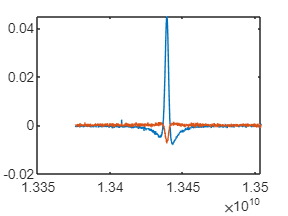

x = dataRes(:, 1);
spc1 = dataRes(:, 2) - dataNonRes(:, 2); % Baseline correction
spc2 = dataRes(:, 3) - dataNonRes(:, 3); % Baseline correction

figure()
plot(x, spc1)
hold on
plot(x, spc2)

Phase correction

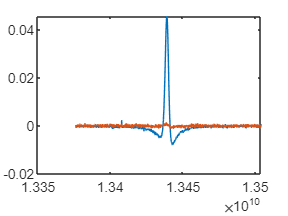

y1 = spc1 + 1i*spc2;
[y2, Phase] = correctPhase(y1, 'Maximum');
y = real(y2);

figure()
plot(x, real(y2))
hold on
plot(x, imag(y2))

## esfit vary field 

esfit with the function pepperFieldOffset returns the value of the field offset directly. When using this method the g-value is fixed to the value of the literature. System

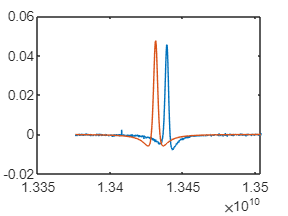

Sys.S = 1/2;
Sys.g = 2.003; % Value from the literature
Sys.lw = [0.0 6]; % MHz [Gaussian Lorentzian]

% Parameter ranges
Vary.g = 0.00;
Vary.lw = [0. 5];

% Parameters of the experiment
% Exp.mwFreq = 1.348; % mT
% Exp.Range = [mhz2mt(min(data.x*1e-6), Sys.g) mhz2mt(max(data.x*1e-6), Sys.g)] % Accepts only [Binit Bfin] and not [Bcenter width]
Exp.Field = 479.1; % mT
Exp.mwRange = [min(x) max(x)]*1e-9; % Accepts only [Binit Bfin] and not [Bcenter width]
Exp.mwPhase = pi/2; % Not completely, apparently
Exp.Harmonic = 1;
Exp.nPoints = numel(x);
ExpVary.Field = 1.5;
% FitOpt.x = data.x;
FitOpt.Verbosity = 0;

figure()
% plot(linspace(min(mhz2mt(data.x*1e-6)), max(mhz2mt(data.x*1e-6)), Exp.nPoints), scaleY(pepper(Sys, Exp), data.spc1))
plot(x, y)
hold on
plot(x, scaleY(pepper(Sys, Exp), y))

% plot(data.x, scaleY(pepper(Sys, Exp), data.spc1))

% esfit(y, @pepper, {Sys, Exp}, {Vary, ExpVary});

Fit = esfit(y, @pepper, {Sys, Exp}, {Vary, ExpVary}, FitOpt);

FID = fopen([Opt.LFolder, '\', 'RSSMB100A_20200504_cw_052_05mA_harm_1_0_parameters.txt']);
Params = textscan(FID, '%s'); B = str2double(Params{1, 1}{16})/10;
Boffset = B - Fit.pfit(2)

Boffset = -1.2748

## Plot (not fancy)

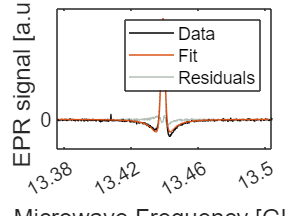

load("GrayColorResiduals.mat");
xx = x*1e-9;
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
ax = nexttile;
h(1) = plot(xx, y, 'Color', 'black');
hold on
h(2) = plot(xx, Fit.fit); 
h(3) = plot(xx, y - Fit.fit, 'Color', GrayColorResiduals);

set(gca, 'Children', [h(2), h(1), h(3)]) % [top, middle, bottom]
set(gca, "Layer", "top")

xlim(setAxLim(xx, 0)); ylim(setAxLim(y, 0.1));
xticks(13.38:.04:13.5);
yticks(0);

labelAxesFig(tL, "Microwave Frequency [GHz]", "EPR signal [a.u.]")

lgd = legendFirstTile(tL, ["Data", "Fit", "Residuals"], h);

## METHOD 2. Difference of g-values

%{
% In this method the g-value is obtained from esfit and then the difference
% between this value and the one from the literature is used to get the
% magnetic field offset.
% System
Sys.S = 3/2;
Sys.g = 2.00211;
Sys.A = 15.9173; % MHz
Sys.lw = [0.009 0.0199]; % mT [Gaussian Lorentzian]
Sys.Nucs = 'N';

% Parameter ranges
Vary.g = 0.002;
Vary.lw = [0.01 0.01];

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(data.B)/10 max(data.B)/10]; % Accepts only [Binit Bfin] and not [Bcenter width]

% Sys2 is to be used if there is another signal, not belonging to NaC60, to 
% be fitted. Fitting this signal is not essential nor interesting and 
% can definitely be avoided.
%{
Sys2.S = 1/2;
Sys2.g = 2.00241;
Sys2.lw = [0.080 0.1597];
Sys2.weight = 63.49;

Vary2.g = 0.001;
Vary2.lw = [0.05 0.05];
Vary2.weight = 10;
%}

esfit('pepper', data.spc, Sys, Vary,  Exp);
% esfit('pepper', data.spc, {Sys, Sys2}, {Vary, Vary2},  Exp);

## ´

Manually save the best-fit parameters using the GUI (usual name of the structure is: fit1) and store it in SysFit2

SysFit2 = ;

bestfit2 = pepperFieldOffset(SysFit2, Exp);

figure()
plot(data.B, data.spc / ((max(data.spc) - min(data.spc))));
hold on
plot(data.B, bestfit2 / ((max(bestfit2) - min(bestfit2))));
legend('data', 'bestfit')

## Field Offset

B_meas = (h * nu) / (mu * g_meas) B_lit = (h * nu) / (mu * g_lit) dB = B_meas - B_lit = (h * nu / mu) * (1 / g_meas - 1 / g_lit)

FieldOffset2 = planck * Params.MWFQ / bmagn * ...
    (1 / SysFit2.g - 1 / Sys1.g); %mT
%}